% filepath: tests/test_impulse_zzy.mlx
%% 测试 impulse_zzy 函数的数值精度
% 与 MATLAB 内置 impulse 函数对比，绘制误差分布

clear; clc;

%% 测试1: 一阶系统
fprintf('========== 测试1: 一阶系统 ==========\n');

========== 测试1: 一阶系统 ==========


num1 = 1;
den1 = [1 2];  % G(s) = 1/(s+2)

% MATLAB 内置函数
sys_matlab = tf(num1, den1);
t_sim = 0:0.01:5;  % 使用统一的时间序列
[y_matlab, t_matlab] = impulse(sys_matlab, t_sim);

% 自定义实现
sys_zzy = tf_zzy(num1, den1);
[y_zzy, t_zzy] = impulse_zzy(sys_zzy, 5);

% 对齐到相同时间点
y_zzy_interp = interp1(t_zzy, y_zzy, t_matlab, 'linear', 'extrap');

% 精度验证（无需插值）
abs_error1 = abs(y_matlab - y_zzy_interp);
mse1 = mean(abs_error1.^2);
mae1 = mean(abs_error1);
max_error1 = max(abs_error1);

% 定位最大误差点
[~, idx_max1] = max(abs_error1);
fprintf('最大误差: %.2e (发生在 t=%.2f s)\n', max_error1, t_matlab(idx_max1));

最大误差: 8.88e-16 (发生在 t=0.30 s)


fprintf('MSE: %.2e\n', mse1);

MSE: 1.47e-31


fprintf('MAE: %.2e\n', mae1);

MAE: 2.43e-16



% 初始瞬态区分析（0-0.5秒）
idx_transient1 = t_matlab <= 0.5;
transient_error1 = abs_error1(idx_transient1);
fprintf('初始瞬态区(0-0.5s)最大误差: %.2e\n', max(transient_error1));

初始瞬态区(0-0.5s)最大误差: 8.88e-16



% 稳态区分析（最后1秒）
idx_steady1 = t_matlab >= (max(t_matlab)-1);
steady_error1 = abs_error1(idx_steady1);
fprintf('稳态区误差均值: %.2e\n\n', mean(steady_error1));

稳态区误差均值: 3.35e-18



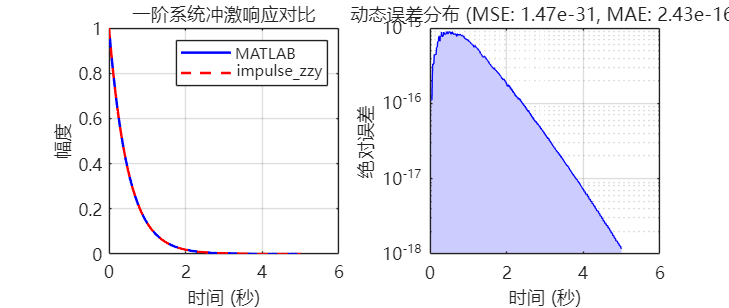


% 动态特性对比图
figure('Name','测试1: 一阶系统', 'Units','normalized','Position',[0.1 0.1 0.8 0.6]);

% 主响应曲线
subplot(1,2,1);
plot(t_matlab, y_matlab, 'b-', 'LineWidth', 1.5, 'DisplayName','MATLAB');
hold on;
plot(t_matlab, y_zzy_interp, 'r--', 'LineWidth', 1.5, 'DisplayName','impulse\_zzy');
ylabel('幅度', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title('一阶系统冲激响应对比', 'FontName','Microsoft YaHei');
legend('FontName','Microsoft YaHei', 'Location','northeast');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei');

% 误差分布图
subplot(1,2,2);
area(t_matlab, abs_error1, 'FaceColor',[0.8 0.8 1], 'EdgeColor','b');
ylabel('绝对误差', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title(sprintf('动态误差分布 (MSE: %.2e, MAE: %.2e)', mse1, mae1),...
      'FontName','Microsoft YaHei');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei', 'YScale','log');


%% 测试2: 二阶欠阻尼系统
fprintf('========== 测试2: 二阶欠阻尼系统 ==========\n');

========== 测试2: 二阶欠阻尼系统 ==========


num2 = [2 1];
den2 = [2 4 4];  % G(s) = (2s+1)/(2s^2+4s+4)

% MATLAB 内置函数
sys_matlab2 = tf(num2, den2);
t_sim2 = 0:0.01:10;  % 使用统一的时间序列
[y_matlab2, t_matlab2] = impulse(sys_matlab2, t_sim2);

% 自定义实现
sys_zzy2 = tf_zzy(num2, den2);
[y_zzy2, t_zzy2] = impulse_zzy(sys_zzy2, 10);

% 对齐到相同时间点
y_zzy_interp2 = interp1(t_zzy2, y_zzy2, t_matlab2, 'linear', 'extrap');

% 精度验证
abs_error2 = abs(y_matlab2 - y_zzy_interp2);
mse2 = mean(abs_error2.^2);
mae2 = mean(abs_error2);
max_error2 = max(abs_error2);

% 定位最大误差点
[~, idx_max2] = max(abs_error2);
fprintf('最大误差: %.2e (发生在 t=%.2f s)\n', max_error2, t_matlab2(idx_max2));

最大误差: 1.22e-15 (发生在 t=0.30 s)


fprintf('MSE: %.2e\n', mse2);

MSE: 1.26e-31


fprintf('MAE: %.2e\n', mae2);

MAE: 2.04e-16



% 初始瞬态区分析（0-0.5秒）
idx_transient2 = t_matlab2 <= 0.5;
transient_error2 = abs_error2(idx_transient2);
fprintf('初始瞬态区(0-0.5s)最大误差: %.2e\n', max(transient_error2));

初始瞬态区(0-0.5s)最大误差: 1.22e-15



% 稳态区分析（最后1秒）
idx_steady2 = t_matlab2 >= (max(t_matlab2)-1);
steady_error2 = abs_error2(idx_steady2);
fprintf('稳态区误差均值: %.2e\n\n', mean(steady_error2));

稳态区误差均值: 1.38e-18



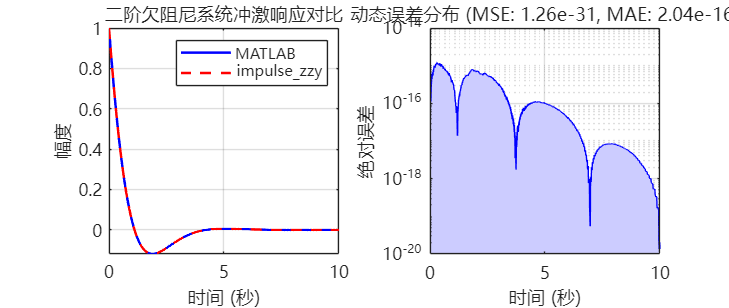


% 动态特性对比图
figure('Name','测试2: 二阶欠阻尼系统', 'Units','normalized','Position',[0.15 0.15 0.8 0.6]);

% 主响应曲线
subplot(1,2,1);
plot(t_matlab2, y_matlab2, 'b-', 'LineWidth', 1.5, 'DisplayName','MATLAB');
hold on;
plot(t_matlab2, y_zzy_interp2, 'r--', 'LineWidth', 1.5, 'DisplayName','impulse\_zzy');
ylabel('幅度', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title('二阶欠阻尼系统冲激响应对比', 'FontName','Microsoft YaHei');
legend('FontName','Microsoft YaHei', 'Location','northeast');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei');

% 误差分布图
subplot(1,2,2);
area(t_matlab2, abs_error2, 'FaceColor',[0.8 0.8 1], 'EdgeColor','b');
ylabel('绝对误差', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title(sprintf('动态误差分布 (MSE: %.2e, MAE: %.2e)', mse2, mae2),...
      'FontName','Microsoft YaHei');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei', 'YScale','log');


%% 总结
fprintf('========== 测试总结 ==========\n');

========== 测试总结 ==========


avg_mse = (mse1 + mse2) / 2;
avg_mae = (mae1 + mae2) / 2;

fprintf('平均 MSE: %.2e\n', avg_mse);

平均 MSE: 1.36e-31


fprintf('平均 MAE: %.2e\n', avg_mae);

平均 MAE: 2.24e-16


fprintf('平均一致小数位数: 约 %d 位\n', floor(-log10(avg_mae)));

平均一致小数位数: 约 15 位



if avg_mae < 1e-10
    fprintf('\n✓ 测试通过! 数值精度达到 10 位以上小数\n');
elseif avg_mae < 1e-6
    fprintf('\n✓ 测试通过! 数值精度达到 6 位以上小数\n');
elseif avg_mae < 1e-4
    fprintf('\n✓ 测试通过! 数值精度达到 4 位以上小数\n');
else
    fprintf('\n✗ 警告: 数值误差较大，需要检查实现\n');
end


✓ 测试通过! 数值精度达到 10 位以上小数
